#  ECEN 5463 | EX 3

Collin Thornton

addpath("TwoLinkRobotMatlabFiles")

## Problem 1

### 1.1 Design a controller such that the following objectives are met for all initial conditions

- For all time, the parameter estimation error, $\tilde{\theta}$, and the tracking error, $e$, are bounded.

- The tracking error, $e$, enters the ball $\bar{B} \left(\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack ,\epsilon \right)$in finite time, where $\epsilon >0$ is some positive constant.

- The constant $\epsilon$ can be made arbitrarily small by tuning control gains

Open loop system: $M\left(q\right)\ddot{q} +V_m \left(q,\dot{q} \right)\dot{q} +F_s \left(\dot{q} \right)+F_d \dot{q} +\mathrm{Sq}=\tau +d\left(t,q,\dot{q} \right)$

where $d\left(t,q,\dot{q} \right)$ is a nonvanishing disturbance bounded by $\bar{d}$ such that $||d\left(t,q,\dot{q} \right)||\le \bar{d} \;\;\forall \left(t,q,\dot{q} \right)$ and the given desired trajectory is $q_d \left(t\right)\in C^2 \left(\Re_{\ge 0} ,\Re^2 \right)$.

The tracking error is defined as $e\left(t\right)=q_d \left(t\right)-\phi_q \left(t\right)$, where $\phi_q \left(t\right)$ is the q-component of the trajectory.

Define the closed-loop control system. For conciseness in the solution, system parameters will be dropped from the $M\left(q\right),V_m \left(q,\dot{q} \right),{\;F}_s \left(\dot{q} \right),\textrm{and}\;d\left(t,q,\dot{q} \right)$ functions.


$$M\left(\ddot{q_d } -\ddot{e} \right)+V_m \left(\dot{q_d } -\dot{e} \right)+F_s +F_d \left(\dot{q_d } -\dot{e} \right)+S\left(q_d -e\right)-\tau -d\left(t\right)=0$$



$$M\ddot{e} =M\ddot{q_d } +V_m \left(\dot{q_d } -\dot{e} \right)+F_s +F_d \left(\dot{q_d } -\dot{e} \right)+S\left(q_d -e\right)-\tau -d\left(t\right)$$


Define $r=\dot{e} +\alpha e$ and $M\dot{r} =M\ddot{e} +M\alpha \dot{e}$

Then $M\ddot{e} =M\dot{r} -M\alpha \dot{e} =M\ddot{q_d } +V_m \left(\dot{q_d } -\dot{e} \right)+F_s +F_d \left(\dot{q_d } -\dot{e} \right)+S\left(q_d -e\right)-\tau -d\left(t\right)$


$$\dot{r} =M^{-1} \left(M\ddot{q_d } +V_m \left(\dot{q_d } -r+\alpha e\right)+F_s +F_d \left(\dot{q_d } -r+\alpha e\right)+S\left(q_d -e\right)-\tau -d\left(t\right)\right)+\alpha \left(r-\alpha e\right)$$


Define $z=\left\lbrack \begin{array}{c}
e\\
r\\
\tilde{\theta} 
\end{array}\right\rbrack$, where $\theta \in \Re^{9\textrm{x1}}$represents the system parameters, $\tilde{\theta} =\theta -\hat{\theta}$, and $\hat{\theta}$ represents the estimate of the system parameters


$$g\left(z,t\right)=\dot{z} =\left\lbrack \begin{array}{c}
\dot{e} \\
\dot{r} \\
\dot{\tilde{\theta} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
r-\alpha e\\
M^{-1} \left(M\ddot{q_d } +V_m \left(\dot{q_d } -r+\alpha e\right)+F_s +F_d \left(\dot{q_d } -r+\alpha e\right)+S\left(q_d -e\right)-\tau -d\left(t\right)+M\alpha \left(r-\alpha e\right)\right)\\
-\dot{\hat{\theta} } 
\end{array}\right\rbrack$$


Define $V\left(z,t\right)=\frac{1}{2}e^T e+\frac{1}{2}r^T \mathrm{Mr}+\frac{1}{2}{\tilde{\theta} }^T \gamma^{-1} \tilde{\theta}$


$$\dot{V} \left(z\right)=\frac{\partial V\left(z,t\right)}{\partial z}g\left(z,t\right)+\frac{\partial V\left(z,t\right)}{\partial t}=\left\lbrack \begin{array}{ccc}
e^T  & r^T M & \gamma^{-1} {\tilde{\theta} }^T 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r-\alpha e\\
M^{-1} \left(M\ddot{q_d } +V_m \left(\dot{q_d } -r+\alpha e\right)+F_s +F_d \left(\dot{q_d } -r+\alpha e\right)+S\left(q_d -e\right)-\tau -d\left(t\right)+M\alpha \left(r-\alpha e\right)\right)\\
-\dot{\hat{\theta} } 
\end{array}\right\rbrack +\frac{1}{2}r^T \frac{\partial \left(M\dot{q} \right)}{\partial q}r$$


By skew symmetry


$$\dot{V} \left(z\right)=e^T \left(r-\alpha e\right)+r^T \left(M\ddot{q_d } +V_m \left(\dot{q_d } +\alpha e\right)+F_s +F_d \left(\dot{q_d } -r+\alpha e\right)+S\left(q_d -e\right)-\tau -d\left(t\right)+M\alpha \left(r-\alpha e\right)\right)-{\gamma^{-1} \tilde{\theta} }^T \dot{\hat{\theta} }$$


Separation of parameters. Define $Y\left(e,r\right)\theta =M\ddot{q_d } +V_m \left(\dot{q_d } +\alpha e\right)+F_s +F_d \left(\dot{q_d } -r+\alpha e\right)+S\left(q_d -e\right)+M\alpha \left(r-\alpha e\right)$


$$\dot{V} \left(z\right)=e^T \left(r-\alpha e\right)+r^T \left(Y\left(e,r\right)\theta -\tau -d\left(t\right)\right)-\gamma^{-1} {\tilde{\theta} }^T \dot{\hat{\theta} }$$



$$\dot{V} \left(z\right)=e^T r-e^T \alpha e+r^T \left(Y\left(e,r\right)\theta -\tau -d\left(t\right)\right)-\gamma^{-1} {\tilde{\theta} }^T \dot{\hat{\theta} }$$


Now we must design $\tau$ and $\dot{\hat{\theta} }$ to stabilize the closed loop system

Let $\tau =Y\hat{\theta} +e+\textrm{kr}$ and $\dot{\hat{\theta} } =\gamma \left(Y^T r-\sigma \hat{\theta} \right)$


$$\dot{V} \left(z\right)=-e^T \alpha e-r^T \textrm{kr}+{\tilde{\theta} }^T \sigma \hat{\theta} -r^T d\left(t\right)$$



$$\dot{V} \left(z\right)=-e^T \alpha e-r^T \mathrm{kr}-{\tilde{\theta} }^T \sigma \tilde{\theta} +{\tilde{\theta} }^T \sigma \theta -r^T d\left(t\right)$$


We know that 


$$\frac{1}{2}\min \left(1,\gamma^{-1} \right)||z||^2 \le V\left(z\right)<\frac{1}{2}\max \left(1,\gamma^{-1} \right)||z||^2$$


We also know that


$$\dot{V} \left(z\right)\le -\alpha ||e||^2 -k||r||^2 -\sigma ||\tilde{\theta} ||^2 +\sigma ||\tilde{\theta} ||||\theta ||-r||\bar{d} \left(t\right)||$$



$$\dot{V} \left(z\right)\le -\min \left(\alpha ,k,\sigma \right)||z||^2 +\max \left(0,-||\bar{d} \left(t\right)||,\sigma ||\theta ||\right)||z||$$



$$\dot{V} \left(z\right)\le -\min \left(\alpha ,k,\sigma \right)||z||^2 +\sigma ||\theta ||||z||$$



$$\dot{V} \left(z\right)\le -\frac{1}{2}\min \left(\alpha ,k,\sigma \right)||z||^2 -\left(\frac{1}{2}\min \left(\alpha ,k,\sigma \right)||z||-\sigma ||\theta ||\right)||z||$$


$\dot{V} \left(z\right)\le -\frac{1}{2}\min \left(\alpha ,k,\sigma \right)||z||^2$ iff $\epsilon \ge \frac{2\sigma ||\theta ||}{\min \left(\alpha ,k,\sigma \right)}$

Let $\alpha_1 =\frac{1}{2}\min \left(1,\gamma^{-1} \right)||z||^2$, $\alpha_2 =\frac{1}{2}\max \left(1,\gamma^{-1} \right)||z||^2$, and $\alpha_3 =\frac{1}{2}\min \left(\alpha ,k,\sigma \right)||z||^2$

#### 1.1.1 Prove that $e$ and $\tilde{\theta}$are bounded for all time

Let us apply Uniform Ultimate Boundedness

H1: $D=\Re^{13}$

H2: $g\left(z\right)$ is Lipschitz continuous and $g\left(0\right)=0$. It satisfies the basic conditions

H3: $V\left(z\right)$ is continously differentiable

H4: $\alpha_{1,2,3}$ are positive definite and continuous iff $\epsilon \ge \frac{2\sigma ||\theta ||}{\min \left(\alpha ,k,\sigma \right)}$

H5: $\alpha_{1,2,3}$ are $K$ class functions on $\bar{B} \left(0,r\right)$

Thus, 


$$||\phi \left(t,t_0 ,z^0 \right)||\le \beta \left(z^0 ,t-t_0 \right)\;\;\forall \;t_0 \le t\le t_0 +T$$



$$||\phi \left(t,t_0 ,z^0 \right)||\le \alpha_1^{-1} \left(\alpha_2 \left(\epsilon \right)\right)\;\;\forall \;t\ge t_0 +T$$


where $\alpha_1^{-1} \left(\alpha_2 \left(\epsilon \right)\right)=\sqrt{\frac{\max \left(1,\gamma^{-1} \right){\left(\frac{2\sigma ||\theta ||}{\max \left(\alpha ,k,\sigma \right)}\right)}^2 }{\min \left(1,\gamma^{-1} \right)}}$  

#### 1.1.2 Prove that $e$ enters $\bar{B} \left(\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack ,\epsilon \right)$in finite time (ie, prove UES)

H1: $D=\Re^{13}$

H2: $g\left(z\right)$ satisfies the basic conditions

H3: $g\left(0\right)=0$

H4: $V\left(z\right)$ is continuously differentiable

H5: Let $\underline{v} ||z||^2 =\alpha_1 \left(z\right)$, $\bar{v} ||z||^2 =\alpha_2 \left(z\right)$, and $v||z||^2 =\alpha_3 \left(z\right)$

H6: Satisfied by H1

Thus, the origin is UGES.

#### 1.1.3 Prove that $\epsilon$ can be made arbitrarily small by tuning control gains

By UUB $||\phi \left(t,t_0 ,z^0 \right)||\le \sqrt{\frac{\max \left(1,\gamma^{-1} \right){\left(\frac{2\sigma ||\theta ||}{\max \left(\alpha ,k,\sigma \right)}\right)}^2 }{\min \left(1,\gamma^{-1} \right)}}\;\;\forall \;t\ge t_0 +T$. By UGES, $T<\infty$.

Thus, $||\phi \left(t,t_0 ,z^0 \right)||\to 0$ as $a,k$ become much greater than $\sigma$

### 1.2 MATLAB experiment to track the desired trajectory

#### 1.2.1 Implement your controller in MATLAB using the roboy dynamics file available in the Exam 3 folder on Canvas.

**Compute **$Y\left(e,r\right)$ **and save to a file**

clearvars;
syms theta [9 1]
syms x [4 1]
syms tau [2 1] 
syms alpha 
syms qd dqd ddqd [2 1]

e = x(1:2);
r = x(3:4) + alpha*e;

q = qd-e;

M = [theta1+2*theta3*cos(q(2)),  theta2+theta3*cos(q(2));
     theta2+theta3*cos(q(2)),    theta2                 ];
Vm = [theta3*sin(q(2))*-x4,  -theta3*sin(q(2))*(-x3-x4);
      theta3*sin(q(2))*-x3,   0                        ];
Fd = diag(theta(4:5));
Fs = theta(6:7).*tanh(-x(3:4));
S = diag(theta(8:9));


f = M*ddqd + Vm*(dqd+alpha*e)+Fs+Fd*(dqd-r+alpha*e)+S*(qd-e)+M*(alpha*(r-alpha*e));


Y = sym(zeros(numel(f),numel(theta)));

for i=1:numel(f)
    for j=1:numel(theta)
        temp = coeffs(f(i,:),theta(j),'All');
        if numel(temp) == 2
            Y(i,j) = temp(1);
        end
    end
end

matlabFunction(simplify(Y), 'File', 'Y', 'Vars', {x,alpha,[qd;dqd;ddqd]});

**Simulate the controller**

clearvars;

p.alpha = 10;     % alpha > 0
p.k     = 100;
p.sigma = 10;
p.gamma = 1;

p.Y = zeros(2,9);
p.e = zeros(2,1);
p.r = zeros(2,1);

% x0 = [q; dq]
q0 = traj(0);


x0 = q0(1:4);     % Pick a random starting positions and velocities

% Random initial guess for theta_hat
theta_hat_dot0 = 5*rand(9,1);

y0 = [x0; theta_hat_dot0];

tspan = [0 10];

%% Animation parameters
L=[1;0.5]; %Link lengths
w=[0.1;0.05]; %Link widths


%%% USE THIS CHECKBOX TO ENABLE ANIMATIONS -> WILL SIGNFICANTLY INCREASE RUNTIME
%
    enableAnimation = false;
%%%

if enableAnimation == 1
    options = odeset(...
    'OutputFcn',@(t,y,flag) nLinkAnimateOutputFcn(t,y,flag,L,w)...
    );
    [t,y] = ode45(@(t,y) closedLoopDynamicsDDR(t,y,p), tspan, y0, options);    
else
    [t,y] = ode45(@(t,y) closedLoopDynamicsDDR(t,y,p), tspan, y0);    
end


q0 = traj(t');
e = q0(1:2,:)' - y(:,1:2);

subplot(2,2,1)
plot(t,e, "LineWidth", 2);

xlabel("t (s)", "Interpreter", "latex")   
legend("Link 1", "Link2");
title("Model based error over time")
ylabel("e(t) (rad)", "Interpreter", "latex")
grid on;
tau = [];

for i = 1:size(y,1)
    tau = [tau controlDDR(t(i), y(i,:)', p)];
end

subplot(2,2,2)

plot(t,tau, "LineWidth", 2);
xlabel('$t$ (s)','Interpreter','Latex');
ylabel('$\tau(t)$ (Nm)','Interpreter','Latex');
legend('Link 1','Link 2');
grid on;
title("Model based torque")

#### 1.2.2 Compare against a PD controller

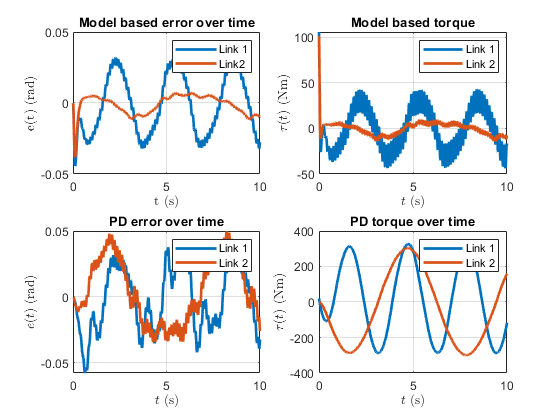

%% Simulation
if enableAnimation == 1
    options = odeset('OutputFcn',@(t,y,flag) nLinkAnimateOutputFcn(t,y,flag,L,w));
    [t,x]=ode45(@(t,x) robotDynamicsExam3(t,x,controlFunExam3(t,x),"Smooth"), tspan,  x0,  options); 
    xlabel('$x$ (m)','Interpreter','Latex')
    ylabel('$y$ (m)','Interpreter','Latex')
else
    [t,x]=ode45(@(t,x) robotDynamicsExam3(t,x,controlFunExam3(t,x),"Smooth"), tspan,  x0); 
end

%% Plots
x=x';
q = x(1:2,:);
qd = [(1 - exp(-2 * t.')) .* cos(2 * t.');
      (1 - exp(-2 * t.')) .* sin(t.')];
e = qd - q;


subplot(2,2,3)
plot(t,e, "LineWidth", 2)
xlabel('$t$ (s)','Interpreter','Latex')
ylabel('$e(t)$ (rad)','Interpreter','Latex')
legend('Link 1','Link 2');
grid on;
title("PD error over time")

subplot(2,2,4)
tau=controlFunExam3(0,x);
plot(t,tau, "LineWidth", 2);
xlabel('$t$ (s)','Interpreter','Latex');
ylabel('$\tau(t)$ (Nm)','Interpreter','Latex');
legend('Link 1','Link 2');
grid on;
title("PD torque over time")

Tuning the PD controller is tricky due to the nonvanishing disturbance. High gains were required to reduce the error to a magnitude comparable to that of the model based controller. The PD controller also exhibits significantly more jerk due to the disturbance. While the model based controller required a significant torque at the initial timestep, the toque decays quickly to less than 100 Nm on each joint. The PD controller continues to require greater than 250 Nm of torque in steady state. This implies that the model aware nature of our derived controller allows for more efficient and robust control.

## Problem 2

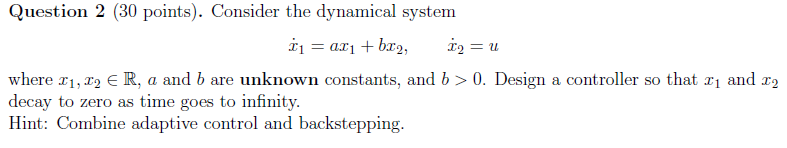

Let $z_1 =x_1$ and $z_2 =x_2 -\phi_1 \left(z_1 \right)$

$z=\left\lbrack \begin{array}{c}
z_1 \\
z_2 
\end{array}\right\rbrack$ and $f\left(z\right)=\dot{z} =\left\lbrack \begin{array}{c}
{\textrm{az}}_1 +b\left(\phi_1 \left(z_1 \right)+z_2 \right)\\
u-\frac{\partial \phi_1 \left(z_1 \right)}{\partial z_1 }\left(az_1 +b\left(\phi_1 \left(z_1 \right)+z_2 \right)\right)
\end{array}\right\rbrack$

Now let $\theta_1 =\frac{a}{b}$ and $\theta_2 =\left\lbrack \begin{array}{c}
a\\
b
\end{array}\right\rbrack$


$$w=\left\lbrack \begin{array}{c}
z\\
\tilde{\theta_1 } \\
\tilde{\theta_2 } 
\end{array}\right\rbrack$$
  
$$g\left(w\right)=\left\lbrack \begin{array}{c}
\dot{z} \\
-\dot{\hat{\theta_1 } } \\
-\dot{\hat{\theta_2 } } 
\end{array}\right\rbrack$$



$$V\left(w\right)=\frac{1}{2b}z_1^2 +\frac{1}{2}z_2^2 +\frac{1}{2}{\tilde{\theta} }_1^T \tilde{\theta_1 } +\frac{1}{2}\tilde{\theta_2^T } \tilde{\theta_2 }$$



$$\frac{\partial V\left(w\right)}{\partial w}=\left\lbrack \begin{array}{cccc}
\frac{z_1 }{b} & z_2  & \tilde{\theta_1^T }  & {\tilde{\theta_2 } }^T 
\end{array}\right\rbrack$$



$$\dot{V} \left(w\right)=\frac{z_1 }{b}\left({\textrm{az}}_1 +b\left(\phi_1 +z_2 \right)\right)+z_2 \left(u-\frac{\partial \phi_1 \left(z_1 \right)}{\partial z_1 }\left(az_1 +b\left(\phi_1 \left(z_1 \right)+z_2 \right)\right)\right)-\tilde{\theta_1^T } \dot{\hat{\theta_1 } } -{\tilde{\theta_2 } }^T \dot{\hat{\theta_2 } }$$



$$\dot{V} \left(w\right)=z_1 \left(\theta_1 z_1 +\phi_1 \right)+z_2 \left(z_1 +u-\frac{\partial \phi_1 \left(z_1 \right)}{\partial z_1 }\left(az_1 +b\left(\phi_1 \left(z_1 \right)+z_2 \right)\right)\right)-\tilde{\theta_1^T } \dot{\hat{\theta_1 } } -{\tilde{\theta_2 } }^T \dot{\hat{\theta_2 } }$$



$$\phi_1 =-\hat{\theta_1 } z_1 -\alpha z_1 =-\left(\hat{\theta_1 } +\alpha \right)z_1$$



$$\dot{V} \left(w\right)=-\alpha z_1^2 +z_1^2 \tilde{\theta_1 } +z_2 \left(z_1 +u+\left(\hat{\theta_1 } +\alpha \right)\left(az_1 +b\left(-\left(\hat{\theta_1 } +\alpha \right)z_1 +z_2 \right)\right)\right)-\tilde{\theta_1^T } \dot{\hat{\theta_1 } } -{\tilde{\theta_2 } }^T \dot{\hat{\theta_2 } }$$



$$Y=\left\lbrack \begin{array}{cc}
z_1  & -\left(\hat{\theta_1 } +\alpha \right)z_1 +z_2 
\end{array}\right\rbrack$$



$$\dot{V} \left(w\right)=-\alpha z_1^2 +z_2 \left(z_1 +u+\left(\hat{\theta_1 } +\alpha \right)Y\theta_2 \right)-\tilde{\theta_1^T } \dot{\hat{\theta_1 } } -{\tilde{\theta_2 } }^T \dot{\hat{\theta_2 } }$$



$$u=-\left(\hat{\theta_1 } +\alpha \right)Y\hat{\theta_2 } -z_1 -\beta z_2$$



$$\dot{V} \left(w\right)=-\alpha z_1^2 -\beta z_2^2 +z_1^2 \tilde{\theta_1 } +z_2 \left(\hat{\theta_1 } +\alpha \right)Y\tilde{\theta_2 } -\tilde{\theta_1^T } \dot{\hat{\theta_1 } } -{\tilde{\theta_2 } }^T \dot{\hat{\theta_2 } }$$



$$\dot{\hat{\theta_1 } } =z_1^2$$



$$\dot{\hat{\theta_2 } } =Y^T z_2 \left(\hat{\theta_1 } +\alpha \right)$$



$$\dot{V} \left(w\right)=-\alpha z_1^2 -\beta z_2^2$$


$\dot{V} \left(w\right)$ is negative semidefinite along $w$

Apply the invariance principle:

1.) $D=\Re^5$

2.) $g\left(w\right)$ satisfies the basic conditions

3.) $V\left(w\right)$ is continuously differentiable

4.) $V\left(w\right)$is radially unbounded. Given any $\beta >0$, $\Omega_{\beta }^{\prime }$ is a filled ellipse, compact, connected, and in $D=\Re^5$ and is positively invariant. Let $\Omega =\Omega_{\beta }^{\prime }$ for any $\beta >0$.

5.) $\dot{V} \left(w\right)$is negaitve semidefinite

6.) $E=\left\lbrace w\in \Omega \;\;|\;\;\dot{V} \left(w\right)=0\right\rbrace =\Omega \cap \left\lbrace \left\lbrack \begin{array}{c}
z\\
\tilde{\theta_1 } \\
\tilde{\theta_2 } 
\end{array}\right\rbrack \in \Re^5 \;|\;z=0\right\rbrace$

7.) Find $M\subset E$, where $M$ is the largest invariant set in $E$.

Need $M$ such that


$$\dot{z} =\left\lbrack \begin{array}{c}
{\textrm{az}}_1 +b\left(-\left(\hat{\theta_1 } +\alpha \right)z_1 +z_2 \right)\\
-\left(\hat{\theta_1 } +\alpha \right)Y\hat{\theta_2 } -z_1 -\beta z_2 +\left(\hat{\theta_1 } +\alpha \right)Y\theta_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$


-$\dot{\hat{\theta_1 } } =z_1^2 =0$

-$\dot{\hat{\theta_2 } } =Y^T z_2 \left(\hat{\theta_1 } +\alpha \right)=0$

Acknowledging $M\in E$


$$\dot{z} =\left\lbrack \begin{array}{c}
0\\
\left(\hat{\theta_1 } +\alpha \right)Y\tilde{\theta_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$


-$\dot{\hat{\theta_1 } } =0=0$

-$\dot{\hat{\theta_2 } } =0=0$

Thus, the largest invariant set is $M=\left\lbrace \left\lbrack \begin{array}{c}
z\\
\tilde{\theta_1 } \\
\tilde{\theta_2 } 
\end{array}\right\rbrack \in \Re^5 \;|\;z,\tilde{\theta_2 } =\overrightarrow{0} \right\rbrace$. Given any $\zeta^0 \in \Omega$, $\lim_{t\to \infty } \;\textrm{dist}\left(\phi \left(t,\zeta^0 \right),M\right)=0$ and $\lim_{t\to \infty } \;\phi_z \left(t,\zeta^0 \right)=0$. The system is LAS.

In other words, $z_1 ,z_2$ decay to to zero as time goes to infinity. Backstepping introduces an affine transformation from $x\to z$, implying that $x_1 ,x_2$ also decay to zero.

## Problem 3

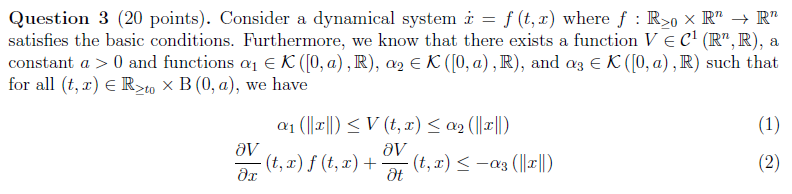

### 3.1 Show that the origin is UAS

H1: Will come back to this...

H2: $f\left(t,x\right)$ satisfies the basic conditions, ie: is locally Lipschitz and piecewise continuous in t

H3: $f\left(t,x\right)$ satisfies the basic conditions

H4: $V$ is stated to be contiuously differentiable

H5: $a_1 ,\alpha_2 ,\alpha_3$ are $K$ class functions, thus are positive definite and are continous

H6: Satisfied by (1) iff $||x||<a$

H7: Satisfied by (2) iff $||x||<a$

H6 & H7 imply that $D=B\left(0,a\right)$      (H1)

All hypothesis are satisfied and the origin is UAS.

#### 3.2 Estimate the region of attraction of the origin in terms of the functions $\alpha_i$ and the constant $a$

The region of attraction consists of all $x$ such that $\alpha_i$ are defined. Thus, it may be defined as $B\left(0,a\right)$.

This is evident as the origin is UAS when $||x||<a$.

function [dy] = closedLoopDynamicsDDR(t, x, p)   
    dx = robotDynamicsExam3(t, x, controlDDR(t, x, p), "Smooth");
    theta_hat_dot = updateLawDDR(t, x, p);
    dy = [dx;theta_hat_dot];
end

function [tau] = controlDDR(t, x, p)
    q0 = traj(t);
    
    p.e = q0(1:2) - x(1:2);
    de  = q0(3:4) - x(3:4);
    p.r = de + p.alpha*p.e;
    
    p.Y = Y(x,p.alpha,q0);
         
    %tau = max(min(p.Y*x(5:13) + p.e + p.k*p.r, 60), -60);
    tau = p.Y*x(5:13) + p.e + p.k*p.r;
end

function [ tau ] = controlFunExam3( t,x )
    %Controller Design
    kp=[300 0;0 300];
    kd = [10 0; 0 10];
    
    qd = [(1-exp(-2*t)) * cos(2*t);
          (1-exp(-2*t)) * sin(t)];
    dqd  = [2.*sin(2.*t).*(exp(-2.*t) - 1) + 2.*cos(2.*t).*exp(-2.*t);
        2.*exp(-2.*t).*sin(t) - cos(t).*(exp(-2.*t) - 1)];
    
    e=qd-[x(1,:);x(2,:)]; 
    de = dqd - [x(1,:);x(2,:)];
    
    tau = kp*e + kd*de;
end


function theta_hat_dot = updateLawDDR(~, x, p)
    theta_hat_dot = p.gamma*(p.Y'*p.r - p.sigma*x(5:13));
end

function [q0] = traj(t)
    qd  = [(1-exp(-2.*t)) .* cos(2.*t);
           (1-exp(-2.*t)) .* sin(t)];
    
    dqd  = [2.*sin(2.*t).*(exp(-2.*t) - 1) + 2.*cos(2.*t).*exp(-2.*t);
            2.*exp(-2.*t).*sin(t) - cos(t).*(exp(-2.*t) - 1)];
    
    ddqd = [-4.*cos(2.*t) - 8.*sin(2.*t).*exp(-2.*t);
             4.*exp(-2.*t).*cos(t) - sin(t) - 3.*exp(-2.*t).*sin(t)];
    
    q0 = [qd;dqd;ddqd];
end